## Poisson Equation

As the first demo, let's solve the *hello world* problem of PDE, the Poisson equation with only Dirichlet boundary conditions:


$$\Delta u=f,\qquad \text{in } \Omega\;,\\
u=g,\qquad\text{on }\partial \Omega\;.
$$


## Test case

To make things easier, let's define the problem with an explicit solution:


$$u=x\text{ }y\left(1−\frac{x}{2}\right)\left(1−y\right)exp\left(x+y\right)\ldotp$$


In order to have such a solution,


$$f=\Delta u=\frac{\partial^2 }{\partial x^2 }u+\frac{\partial^2 }{\partial y^2 }u\ldotp$$


You can use Matlab symbolic toolbox to get an exact expression for $f$. But it's not too hard to solve it by hand to get


$$\begin{array}{l}
f=−y\left(1−y\right)\left(1−x−\frac{x^2 }{2}\right)exp\left(x+y\right)\\
\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }\text{ }−x\left(1−\frac{x}{2}\right)\left(−3y−y^2 \right)exp\left(x+y\right)\ldotp 
\end{array}$$


And we will just let $g=u$, but with some extra test.

f = @(x,y) -y.*(1-y).*(1-x-x.^2/2).*exp(x+y) ...
           -x.*(1-x/2).*(-3*y-y.^2).*exp(x+y);
u = @(x,y) x.*y.*(1-x/2).*(1-y).*exp(x+y);
g = @(x,y) u(x,y)/all(x==1|x==-1|y==1|y==-1); % will throw error if 
                                   % any (x(i), y(i)) is not on boundary

## Domain

First we define our domain $\Omega$ and generate a function space on it with finite element of choice:

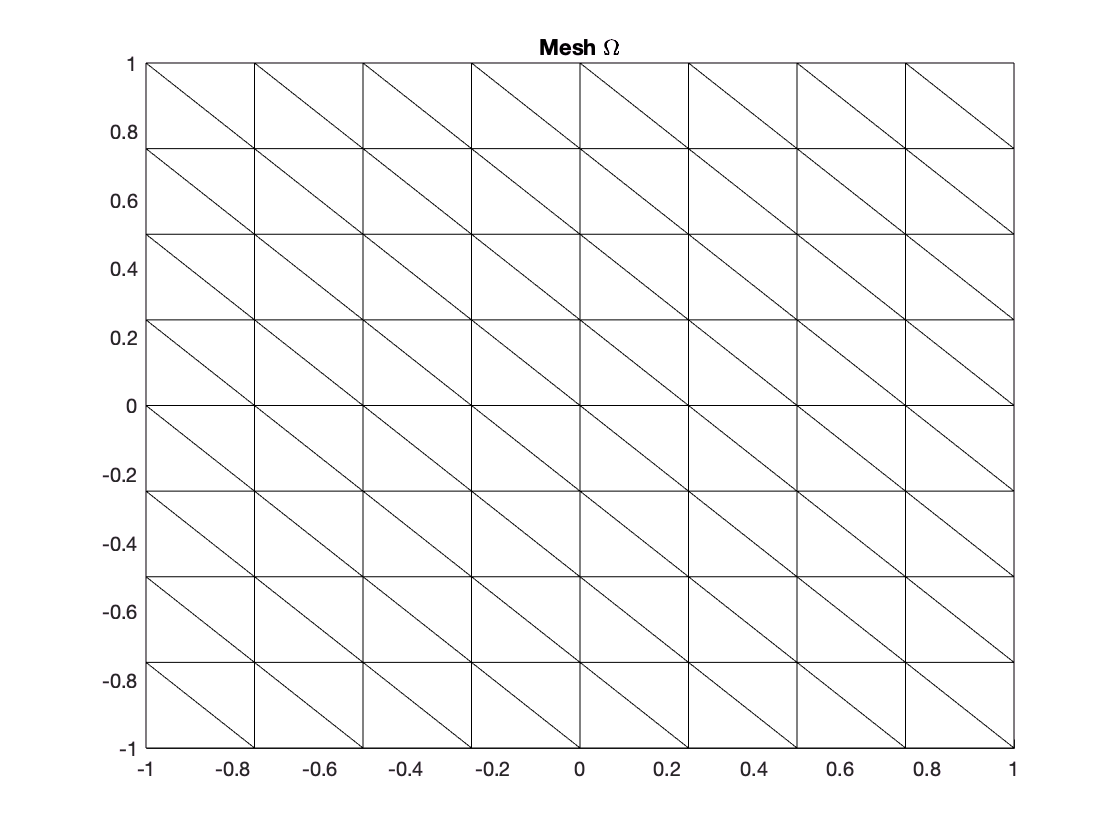

addpath('..')
import MatFem.*
domain = [-1 1 -1 1];
nx = 8;
ny = 8;
shape = [nx ny];
mesh = rectMesh(domain, shape);
mesh.plot();
title('Mesh \Omega')

## Function Space

Function Space is one of the important class implemented in **MatFem**. It is inspired of course by the greate FEniCS, and basically follows the idea introduced in [the FEniCS Book](https://fenicsproject.org/book/).

Now let's construct a degree 2 function space with 9 quadrature points in each element:

V = MatFem.mesh2spc(mesh, 2, 9);
V.plot()
title('Function space of degree 2 with 9 quadrature points in each element')

Now we have our function space, we can take a look at what our real solution look like by calling the `plotu `method:

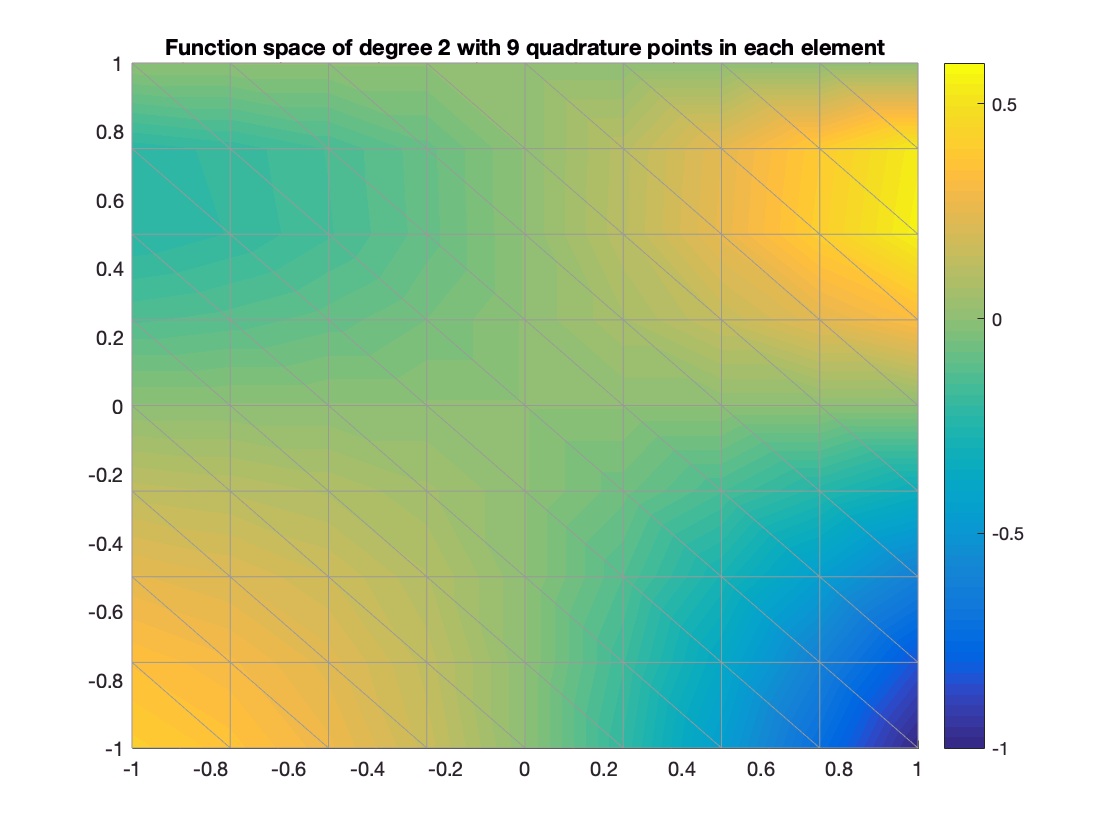

V.plotu(u);

## Assembling

Denote $v$ as the test function on our function space. The variational form of the Poisson equation is


$$\int_\Omega \nabla v\cdot\nabla u =\int_\Omega fv$$


which can be further expanded to


$$\int_\Omega v_xu_x+\int_\Omega v_yu_y=\int_\Omega fv$$


Now the function `assemble`, as the name might suggest, can assemble the matrix and the vector for all the above terms.

`assemble(spc, ders, f)`

This function can be used to assemble both the matrix and the vector for integration in the form


$$\int f\cdot \frac{\partial^{a+b}v}{\partial x^a\partial y^b}\cdot\frac{\partial^{c+d}u}{\partial x^c\partial y^d}d\Omega\;,$$


on function space `spc`. The orders of derivatives $a, b, c, d$are given by the argument `ders=[a, b; c, d]`. 

When `size(ders)==[1,2]`, the $u$ term will be omitted and a vector will be returned. Which can be used to assemble the right hand side.

So our linear system can be assembled as:$\int_\Omega u_x v_x$ 

A = assemble(V, [1 0; 1 0]); % f=1 when not given

plus$\int_\Omega u_yv_y$ 

A = A + assemble(V, [0 1; 0 1]);

equals $\int_\Omega fv$ 

b = assemble(V, [0 0], f);  % here f is the source term we defined before. 
                           % And since we are not differentiating v, ders=[0,0]

## Boundary Condition

Boundary conditions, both Dirichlet and Neumann, are controled by `BndCond` class.

Here we have a boundary for a rectangular shaped domain and every edge has a dirichlet boundary condition. So we mark all the boundary edges by `'d'`.

bc = MatFem.rectBndCond(V, 'd', domain);

Then the dirichlet boundary condition can be applied through

[b, A] = bc.applyDir('d', g, b, A);

## Solve

This is Matlab. Every problem can be solved by a backslash ; )

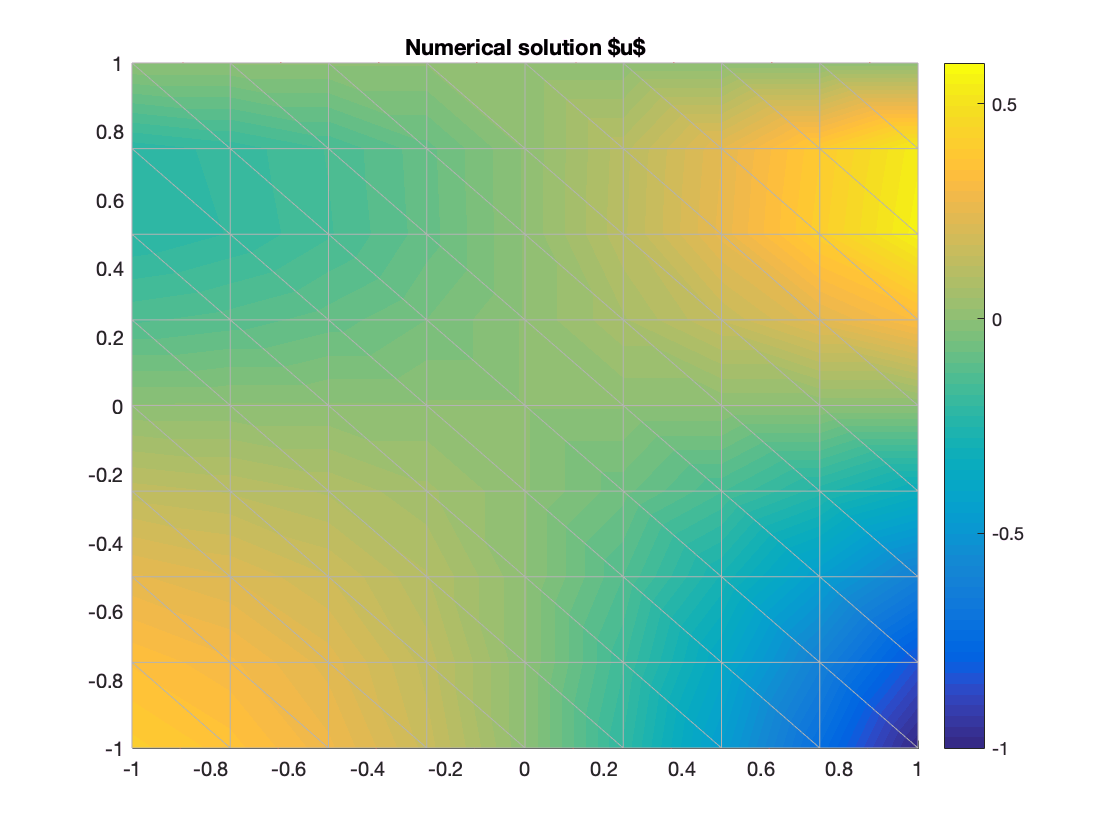

u_n = A \ b;
V.plotu(u_n, 'EdgeColor', [.7, .7, .7]);
title('Numerical solution $u$')

## Error

`errorNorm` can be used to calculate $L^\infty$, $L^2$ and $H^1$ norm of errors, given true solution `u_true` as a function handle. `u` can even be vector valued and we'll see examples in later demos.

e_L2 = MatFem.errorNorm(V, u_n, u, 'L2') % argument norm_type is case insensitive

e_L2 = 0.0010

e_inf = MatFem.errorNorm(V, u_n, u, 'inf')

e_inf = 0.0033

In order to calculate the $H^1$ norm, we need to supply derivatives of true solution, as pass them into `u_true` as a cell, `{dudx, dudy}`. If `u` is vector valued, then `u_true` is passed in the form

`{du1dx, du1dy; `

` du2dx, du2dy; `

` ...}`

dudx = @(x,y) .5*(x.^2-2).*(y-1).*y.*exp(x+y);
dudy = @(x,y) .5*x.*(x-2).*(y.^2+y-1).*exp(x+y);
error_H1 = MatFem.errorNorm(V, u_n, {dudx, dudy}, 'h1')

error_H1 = 0.0354

We can get these three type of errors in a table all together by calling

e_table = MatFem.calcErrors(V, u_n, u, {dudx, dudy}, 1/16)

e_table =       h       error_inf    error_L2     error_H1
    ______    _________    _________    ________
    '1/16'    0.0032769    0.0010409    0.035352

This is helpful if we want to check convergence rate when decreasing `h`, the cell size, as implemented in `i_poisson.m`

run i_poisson.m

      h       error_inf      error_L2      error_H1 
    ______    __________    __________    __________
    '1/8'     0.00037975    0.00010972     0.0079338
    '1/16'    5.4347e-05    1.5035e-05     0.0021115
    '1/32'     7.284e-06    1.9687e-06    0.00054465
    '1/64'    9.4331e-07    2.5189e-07    0.00013831
Elapsed time is 7.216576 seconds.
